# Prelim

Connor Emmons, Riley Lubic

Doc: We used MatLab's documentation and various online resources to use some of the functions in this code. We used class resources such as notes, in class questions, and the provided project hints files. No other resources used.

## Mass Properties

### 1) Location of S/C COM from CAD Frame

In order to find the total center of mass of the spacecraft from the masses and locations of centers of mass of the spacecraft body and the payload, multiply the vector of each individual mass by the mass of that component. Then, sum the resulting vectors and divide by the total mass of the components to get the S/C COM.

m_sc = 148.5;
m_pl = 10.5;

r_sc_B = [-0.01; 0.01; 0.37];
r_pl_B = [0; 0; -0.05];

sc_COM = (m_sc*r_sc_B + m_pl*r_pl_B)/(m_sc + m_pl)

sc_COM =    -0.0093
    0.0093
    0.3423


### 2) Total S/C Inertia Matrix in CAD Frame

In order to find the total inertia matrix of the spacecraft from the inertia matrices of the spacecraft body and the payload, use the parallel axis theorem on both components, then add the resulting inertia matrices to get the total S/C inertia matrix.

I_sc_B = [16.20 -0.40 -0.40;
    -0.40 13.30 -0.40;
    -0.40 -0.40 6.40];
I_pl_B = eye(3).*[0.10; 0.10; 0.05];

I_COM = (I_sc_B + m_sc*(r_sc_B'*r_sc_B*eye(3) - r_sc_B*r_sc_B')) +...
    (I_pl_B + m_pl*(r_pl_B'*r_pl_B*eye(3) - r_pl_B*r_pl_B'))

I_COM =    36.6707   -0.3852    0.1494
   -0.3852   33.7707   -0.9495
    0.1494   -0.9495    6.4797


### 3, 4) DCM ($C_{P/B}$) for Principal Frame and Principal Inertia Matrix

In order to find the directional cosine matrix that relates the spacecraft's body frame to a principal frame, find the eigenvalues and eigenvectors of the inertia matrix in the body frame. Arranging the eigenvectors as the columns of a 3x3 matrix such that the resulting matrix is close to identity gives the DCM $C_{B/P}$ and the corresponding eigenvalues are $I_1$, $I_2$, and $I_3$. Taking the transpose of $C_{B/P$ gives $C_{P/B}$. Because any scalar multiple of an eigenvector is also an eigenvector corresponding to the same eigenvalue, multiply by -1 as necessary to get close to the identity matrix.

[V, D] = eig(I_COM);

C_BP = flip(V, 2).*[-1;1;1]'

C_BP =     0.9912    0.1324   -0.0045
   -0.1322    0.9906    0.0347
    0.0090   -0.0338    0.9994


C_PB = C_BP'

C_PB =     0.9912   -0.1322    0.0090
    0.1324    0.9906   -0.0338
   -0.0045    0.0347    0.9994



I_P = flip(flip(D, 2), 1)

I_P =    36.7235         0         0
         0   33.7516         0
         0         0    6.4461


## Control Mode 1

### 1) Derive Linearized EOMs in SS Form

Begin with the nonlinear equations of motion between the body and the orbital frame.

syms I_r I_p I_y w_c gc1 gc2 gc3 q0 ...
    w1 w2 w3 q1 q2 q3 h1 h2 h3

% Define variables
I_T = [I_r 0 0; 0 I_p 0; 0 0 I_y];
W = [w1; w2; w3];

By some miracle, the spacecraft is only spinning about its second axis.

W_c = [0; -w_c; 0];
h_w = [h1; h2; h3];
g_c = [gc1; gc2; gc3];
q = [q1; q2; q3];
W_x = skew(W);
W_c_x = skew(W_c);

% Define DCM
Q1 = [2*q0^2-1+2*q1^2; 2*q1*q2-2*q0*q3; 2*q1*q3+2*q0*q2];
Q2 = [2*q1*q2+2*q0*q3; 2*q0^2-1+2*q2^2; 2*q2*q3-2*q0*q1];
Q3 = [2*q1*q3-2*q0*q2; 2*q2*q3+2*q0*q1; 2*q0^2-1+2*q3^2];
Q_DCM = [Q1 Q2 Q3];

% Define nonlinear equations for S/C dynamics
f = [I_T\(-I_T*(-W_x*Q_DCM + Q_DCM*W_c_x)*W_c - ...
    cross((W - w_c*Q2), (I_T*(W-w_c*Q2) + h_w)) + g_c + ...
    cross(3*w_c^2*Q3, I_T*Q3)); ...
    -1/2 * W' * q; ...
    -1/2 * W_x * q + 1/2 * q0 * W; ...
    -g_c];

Note that there are 10 distinct states: 3 relating to angular velocity between the frames, 4 relating to the quaternion describing the relationship between the two frames, and 3 relating to the angular momentum of the spacecraft. Because the quaternion is defined to be unit in length and the satellite is pointing downward (along one of the three axes in the LVLH frame), only three components of the quaternion are required to fully describe the relationship between the body frame and the orbital frame. Specifically, $q_0$ is no longer required, and therefore the number of states decreases by one.

% Define state vector
x = [W; q; h_w];

Taking the partial derivatives of each of the equations wrt each of the states yields a 10 by 9 matrix containing the partial derivatives of each equation with respect to each state. Each row represents an equation and each column represents a different variable which the equation was derived with respect to.

% Define Jacobian
A = jacobian(f, x);

% Define variables object
vars = {W, q, h_w, I_r, I_p, I_y, w_c, q0, gc1, gc2, gc3};

% Convert to function
A_fcn = matlabFunction(A, 'Vars', vars);

Linearizing about $\bar{\omega}=0$ and $\mathbf{q}=0$ allows for the following values to be used.

% Define specific values for the state variables and parameters
W_eq = [0; 0; 0];           
q_eq = [0; 0; 0];           
h_w_eq = [h1; h2; h3];      
I_r_val = I_r;              
I_p_val = I_p;              
I_y_val = I_y;              
w_c_val = w_c;              
q0_val = 1;                 
gc_val = [gc1; gc2; gc3];   

Evaluating the Jacobian with the updated values above produces the $\mathbf{A}$ matrix.

% Evaluate the Jacobian using function
A_eq = A_fcn(W_eq, q_eq, h_w_eq, I_r_val, I_p_val, I_y_val, w_c_val, q0_val, gc_val(1), gc_val(2), gc_val(3));
disp(simplify(A_eq));

$$\begin{array}{l} \left(\begin{array}{ccccccccc} 0 & -\frac{h_{3}}{I_{r}} & \frac{\sigma_{1}}{I_{r}} & \frac{2\,w_{c}\,\left(h_{2}-4\,I_{p}\,w_{c}+4\,I_{y}\,w_{c}\right)}{I_{r}} & 0 & 0 & 0 & 0 & \frac{w_{c}}{I_{r}}\\ \frac{h_{3}}{I_{p}} & 0 & -\frac{h_{1}}{I_{p}} & -\frac{2\,h_{1}\,w_{c}}{I_{p}} & -\frac{6\,{w_{c}}^{2}\,\left(I_{r}-I_{y}\right)}{I_{p}} & -\frac{2\,h_{3}\,w_{c}}{I_{p}} & 0 & 0 & 0\\ -\frac{\sigma_{1}}{I_{y}} & \frac{h_{1}}{I_{y}} & 0 & 0 & 0 & \frac{2\,w_{c}\,\left(h_{2}-I_{p}\,w_{c}+I_{r}\,w_{c}\right)}{I_{y}} & -\frac{w_{c}}{I_{y}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0.5000 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0.5000 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0.5000 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=h_{2}-I_{p}\,w_{c}+I_{r}\,w_{c}+I_{y}\,w_{c} \end{array}$$

Define the input torques as the control input. Note that there are three components, which represent the control torqud about each axis.

% Define control input
u = g_c;

Similar to before, taking the partial of the 10 equations with respect to each of the control torques and evaluating the result at specific control torques (left symbolically for the purposes of this derivation) yields the $\mathbf{B}$ matrix.

% Define Jacobian
B = jacobian(f, u);

% Convert to function
B_fcn = matlabFunction(B, 'Vars', vars);

% Evaluate the Jacobian using function
B_eq = B_fcn(W_eq, q_eq, h_w_eq, I_r_val, I_p_val, I_y_val, w_c_val, q0_val, gc_val(1), gc_val(2), gc_val(3));
disp(B_eq);

$$\left(\begin{array}{ccc} \frac{1}{I_{r}} & 0 & 0\\ 0 & \frac{1}{I_{p}} & 0\\ 0 & 0 & \frac{1}{I_{y}}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ -1 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

Because a full state linear quadratic regulator will be used for the lab, letting $\mathbf{C}$ be the identity matrix allows the outputs of the system to be the states of the system. This system is uncoupled, so the $\mathbf{D}$ matrix is zero.

C_eq = eye(10);
disp(C_eq);

     1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     1



D_eq = 0;
disp(D_eq);

     0



### 2) Spacecraft Block Diagram with Control and Actuation

The plant portion of the block diagram is derived from the standard expression of a system in state space form, which is described by the following equations.


$$\dot{\bar{x}}=\mathbf{A}\bar{x}+\mathbf{B}\bar{u}$$



$$\bar{y}=\mathbf{C}\bar{x}+\mathbf{D}\bar{u}$$


Because the system is uncoupled (i.e., the inputs do not directly affect the output without affecting the states), the coupling matrix $\mathbf{D}$ is zero and is not shown in the diagram. The states are fed back and compared to the reference, which are the desired states. The difference between the desired states and the actual states is computed and multiplied by some gain matrix $\mathbf{K}$, which is the LQR and is determined by the methods governing such a regulator. The output of the LQR is given to the reaction wheel actuators, which determine the speeds of the wheels. 

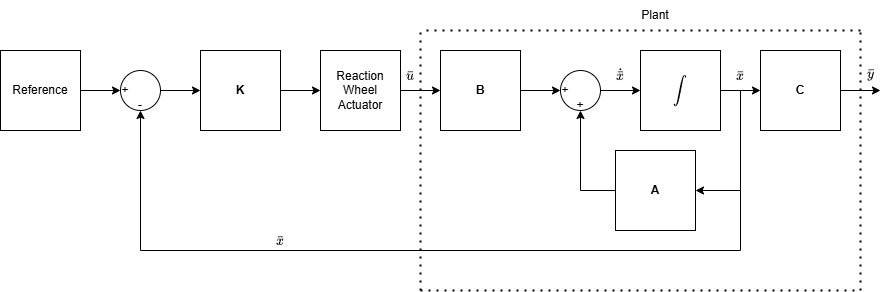

### 3) Wheel Operation Recommendations

We recommend that the wheels be nominally spinning at half of their maximum angular velocity, which would have them spinning at 3750 rpm. The reason that we do not recommend starting the reaction wheels at zero is due to start up delays in the electrical circuit which could create inaccuracies or lackluster response in the control. Placing the "zero point" of the wheel at 3750 rpm removes this issue and means that the wheel never has to accelerate from zero like it would if the "zero point" was at 0 rpm. The downside of this is potentially less maximum control, though this can likely be mitigated by controller design.

## Control Mode 0

global w_c_val k2

% Initialize variables
MU = 398600.5; R = 6378.137 + 500;
w_c_val = sqrt(MU/R^3);

% Calculate pitch libration frequency
k2 = (I_P(1,1) - I_P(3,3)) / I_P(2,2);
w_l = sqrt(3*w_c_val^2*k2)

w_l = 0.0018


% Calculate pitch libration period in minutes
P = inv(w_l/(2*pi))/60

P = 57.6758

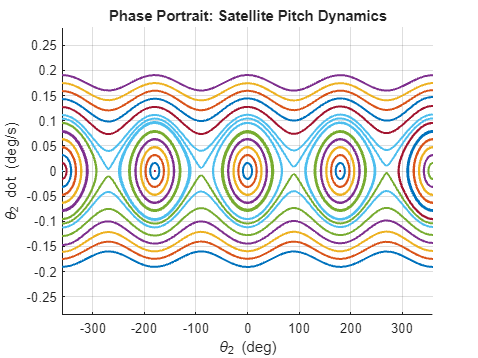


phase_portrait()

Consider the largest oscillation on the phase plot about $\theta_2=0$ and $\dot{\theta}_2=0$. As the initial angular velocity approaches the angular velocity at which the spacecraft stops oscillating and begins tumbling, the intersection of the right side of the sinusoval and the horizontal line for $\dot{\theta}_2=0$ approaches $\theta_2=\frac{\pi}{2}$. Note that the equation governing the shape of the sinusoval on the phase plot is $\dot{\theta}_2=\pm\sqrt{3\omega_c^2k_2sin^2(\theta_2)}$ if the integration constant $c$, which comes from integrating the equation $\ddot{\theta}_2+3\omega_c^2k_2sin(\theta_2)cos(\theta_2)=0$ once, is taken to be zero. Thus, plugging in $\theta_2=\frac{\pi}{2}$ into this equation yields the transition angular velocity where the spacecraft begins tumbling. Interestingly, when $\theta_2=\frac{\pi}{2}$, the equation simplifies to $\dot{\theta}_2=\pm\sqrt{3\omega_c^2k_2}$, which is the libration frequency. This makes sense because if the spacecraft is spinning faster than the oscillations described by the libration frequency, those will dominate and the spacecraft will tumble instead of oscillate.

omega_tumble = [-rad2deg(sqrt(3*w_c_val^2*k2)); rad2deg(sqrt(3*w_c_val^2*k2))]

omega_tumble =    -0.1040
    0.1040
